# Step 6: シミュレーションの結果

`net.simulate` の実行のオプションと、結果（`ResultODE`）からデータを取り出す方法をまとめます。シナリオ（外乱）の作り方は Step 5 で説明しています。

この Step は、GUILDA の基本的な流れの赤枠の部分です。

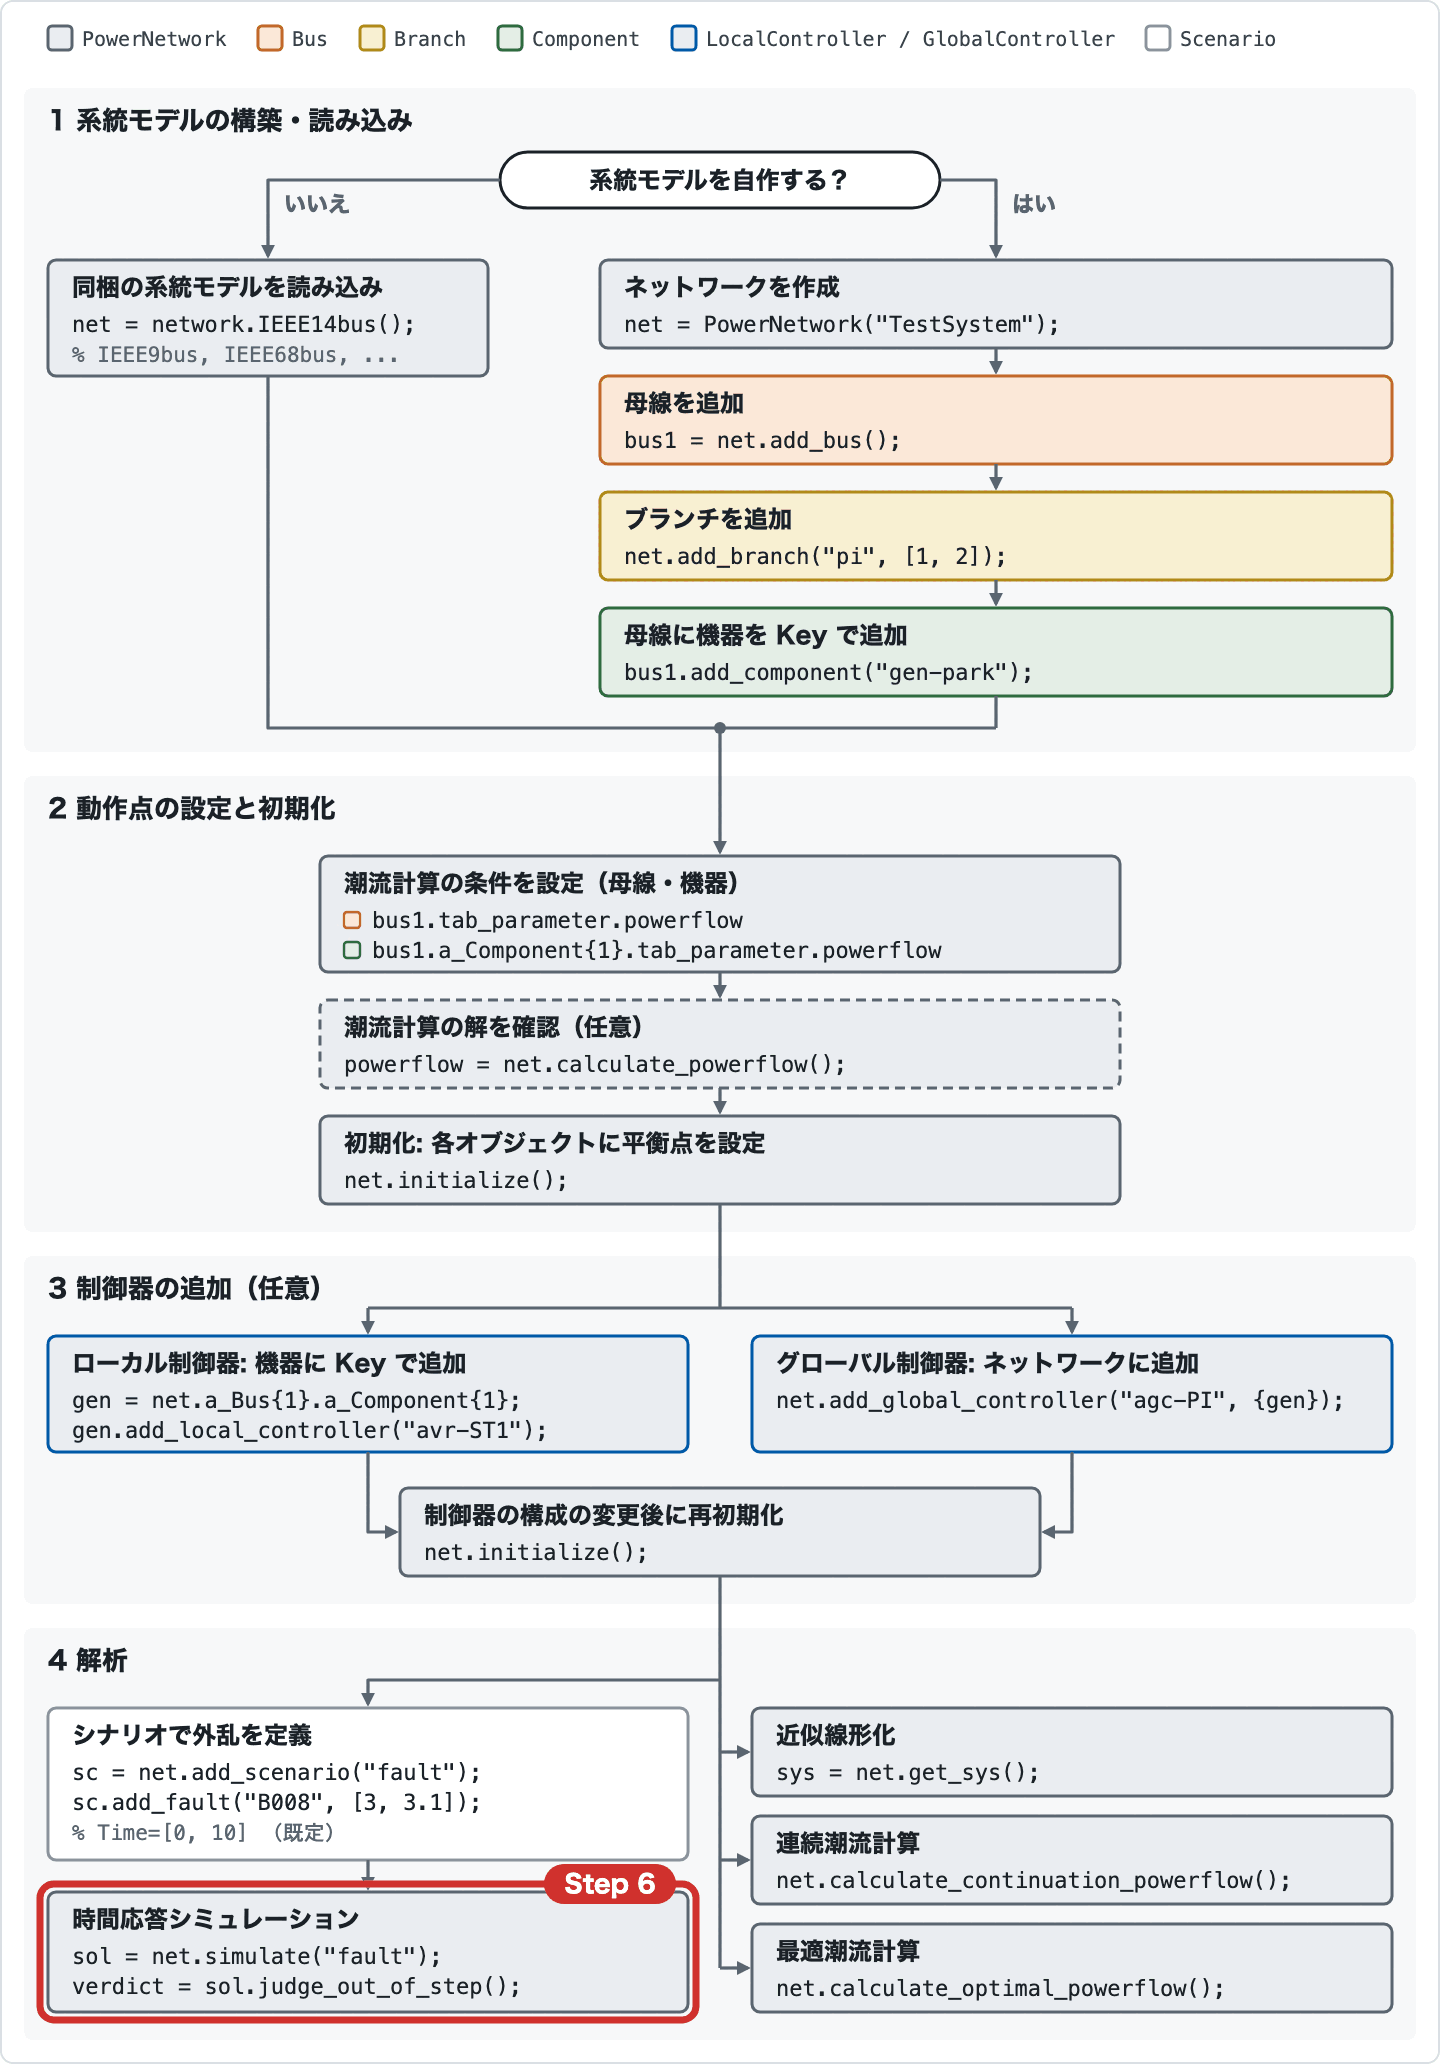

## この Step で分かること

- `simulate` の 3 つの出力（結果、`flag`、`output`）と、オプション（ソルバー、許容誤差、出力の時刻、脱調での停止、制限時間など）の指定

- `ResultODE` の中身: 時刻 `rv_t`、変数の一覧 `tab_variable` と軌道 `rm_variable`、母線と機器ごとに見る `odeResults`

- 1 つの量の時間応答（`get_trajectory`）と、ある時刻の値（`get_point`）の取り出し方

- `plot_trajectory` での図の描き方と、`judge_out_of_step` での脱調の判定

- 結果のファイルへの書き出し（`export`）

各節のコードは、その節の作業に要るものだけです。中身を表示して確かめるコードは「**確かめる（省略できます）**」の下に分けてあります。飛ばしても、最後まで実行できます。

**注意:** GUILDA を起動してから（`>> GUILDA`）実行してください。

## 1. 準備: 系統とシナリオ

IEEE 9 母線系統を読み込んで平衡点を求め、母線 7 を 1 秒から 0.1 秒間地絡させるシナリオを作ります。

net = network.IEEE9bus(LocalController=true);
[~, flag] = net.initialize();
sc = net.add_scenario("fault", Time=[0 5]);
evFault = sc.add_fault("B007", [1, 1.1]);

## 2. 実行と 3 つの出力

`simulate` は、結果（`ResultODE`）、`flag`、`output` の 3 つを返します。

[result, flag, output] = net.simulate("fault", Progress="none");
flag

flag = 1

`flag` は、終わりの時刻まで計算できたら 1 です。ほかの値は次のとおりです。

**確かめる（省略できます）**

`output` には、計算できた時刻 `tEnd`、フェーズの数 `nPhases`、計算できたフェーズの数 `nPhasesDone`、メッセージ `message` などが入ります。`phases` はフェーズの一覧です。

output

output = フィールドをもつ struct:
           tEnd: 5
        nPhases: 3
    nPhasesDone: 3
         phases: [3×5 table]
       isSparse: 1
      exception: []
      outOfStep: [0×0 struct]
        message: "The simulation reached t = 5 s (3 phases)."


output.phases

ans = 3×5 table
    t1     t2     Fault001    NoAction1    NoAction3
    ___    ___    ________    _________    _________

      0      1     false        true         false  
      1    1.1     true         false        false  
    1.1      5     false        false        true   


フェーズは外乱の組み合わせが変わらない区間です。`t1`・`t2` がフェーズの始まりと終わりの時刻、`Fault001` などイベントのタグの列が、そのフェーズでそのイベントが有効かどうかです（`NoAction<番号>` は外乱の変化がない区切りの印です）。`flag` と `output` は結果の中にも入っています。計算に使った設定は `options`、計算時間 [s] は `r_elapsed` です。

result.l_success

ans = logical
   1


result.options

ans = フィールドをもつ struct:
                  Solver: "ode15s"
               Tolerance: 1.0000e-04
       AbsoluteTolerance: 1.0000e-06
                 MaxStep: NaN
             InitialStep: NaN
    SeparateComplexParts: 0
              SampleTime: NaN
         StopOnOutOfStep: 0
               StopAngle: 360
               TimeLimit: Inf
                Progress: "none"
                 Verbose: 0
                 PlotFcn: "none"


result.r_elapsed

ans = 0.5135

## 3. 実行のオプション

Name=Value のオプションで、その呼び出しだけ計算の方法を変えられます。既定値は `GUILDA.setting` の `TimeSimulation` で変えます（Step 11）。この節では次のオプションを使います。

- `Solver`: ODE ソルバー。質量行列が特異な DAE を解ける `"ode15s"`（既定）と `"ode23t"` から選びます。

- `Tolerance`、`AbsoluteTolerance`: 相対許容誤差と絶対許容誤差。

- `SampleTime`: 結果を残す時刻の間隔 [s]。ソルバーのステップを変えずに、結果を残す時刻だけを等間隔にします（フェーズの始まりと終わりの時刻も残ります）。

- `TimeLimit`: 計算時間の上限 [s]。

- `StopOnOutOfStep`: 脱調したら計算を止める（脱調とみなす角度の差は `StopAngle`、既定 360°）。

- `Progress`: 進み具合の表示。`"none"` で表示しません。既定の `"dialog"` は、計算が 0.5 秒以上かかったときだけ小さな画面を開きます。

`Format`（10 節）と、最大のステップ幅 `MaxStep` などの [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=simulate')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。

### 3.1 ソルバー・許容誤差・出力の時刻

ソルバーを `ode23t` にし、許容誤差を小さくし、結果を 0.01 秒ごとに残します。

resFine = net.simulate("fault", Solver="ode23t", Tolerance=1e-6, AbsoluteTolerance=1e-8, SampleTime=0.01, Progress="none");

**確かめる（省略できます）**

今の既定値は `GUILDA.config` で表として見られます。

GUILDA.config("TimeSimulation", Format="table")

ans = 13×4 table
             Name               Type           Value                                                                                                            Description                                                                                                   
    ______________________    _________    ______________    _________________________________________________________________________________________________________________________________________________________________________________________________________________

    "Solver"                  "select"     {["ode15s"  ]}    "Solver of the MATLAB ode object (a solver for DAEs)"                                                                                                                                                            
    "Tolerance"               "double"     {[1.0000e-04]}    "Relative error tolerance, 'RelativeTolerance' of the ode object (1e-15 <= tol <= 1e-3)"                    

オプションを 1 つずつ変えて計算し、発電機 2 の回転の速さを重ねて描きます。結果の時刻の数も比べます。

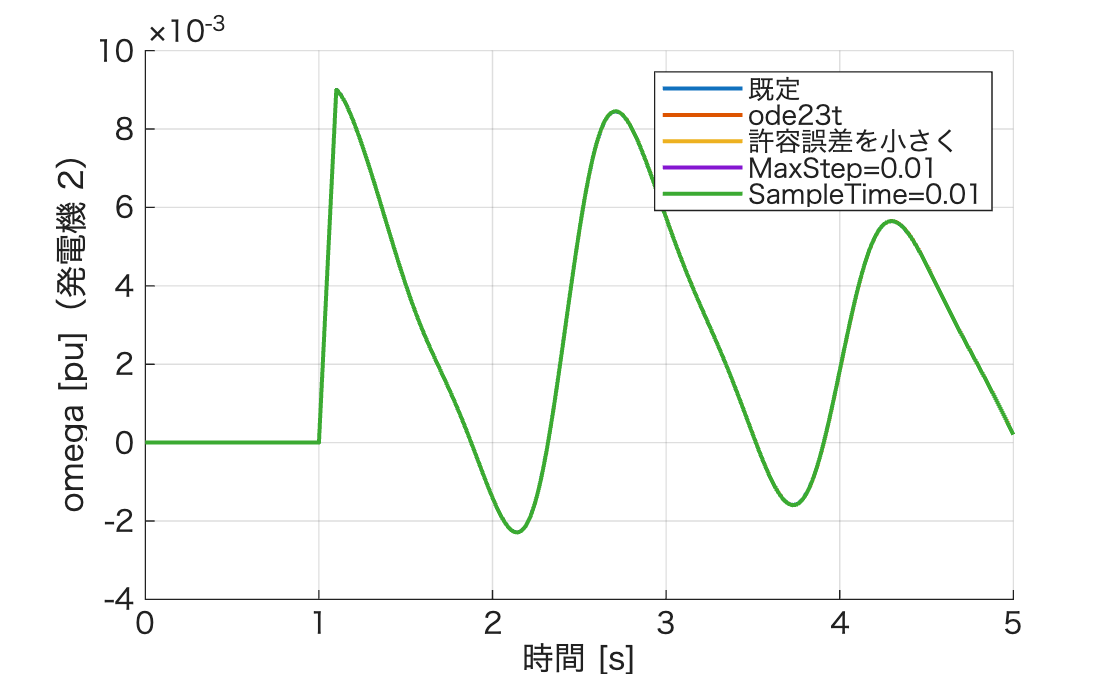

c_option = {{}, {"Solver", "ode23t"}, {"Tolerance", 1e-6, "AbsoluteTolerance", 1e-8}, {"MaxStep", 0.01}, {"SampleTime", 0.01}};   % 名前と値の組
sv_case = ["既定", "ode23t", "許容誤差を小さく", "MaxStep=0.01", "SampleTime=0.01"];
iv_nTime = zeros(size(sv_case));
figure
hold on
for k = 1:numel(c_option)
    res = net.simulate("fault", c_option{k}{:}, Progress="none");
    iv_nTime(k) = numel(res.rv_t);
    tab_omega = res.get_trajectory("omega", Owner="B002SG1");
    plot(tab_omega.t, tab_omega.B002SG1, LineWidth=1.5)
end
hold off
grid on; xlabel("時間 [s]"); ylabel("omega [pu]（発電機 2）")
legend(sv_case, Location="northeast");

iv_nTime

iv_nTime =    304   594   614   595   503


numel(resFine.rv_t)

ans = 503

どの設定でも応答はほとんど同じで、線が重なって最後に描いた線だけが見えます。`iv_nTime` は上の凡例の順の、結果の時刻の数です。

### 3.2 計算時間の上限（TimeLimit）

`TimeLimit` を超えると、その時刻までの結果を返して止まります（`flag` は 0、警告が出ます）。

[resLimit, flag] = net.simulate("fault", TimeLimit=0.05, Progress="none");

flag

flag = 0

**確かめる（省略できます）**

resLimit.output.message

ans = "The simulation stopped at t = 0.1 s of 5 s in phase 1: the computation time exceeded TimeLimit = 0.05 s. Increase TimeLimit (Inf for no limit)."

### 3.3 脱調で止める（StopOnOutOfStep）

`StopOnOutOfStep=true` は、slack 母線の発電機との回転子の角度の差が `StopAngle` を超えたところで止めます。地絡を 0.3 秒に延ばして試し、その後で地絡を元の 0.1 秒に戻します。

evFault.edit(Time=[1, 1.3]);
[resStop, flag] = net.simulate("fault", StopOnOutOfStep=true, Progress="none");
flag

flag = 2

evFault.edit(Time=[1, 1.1]);

**確かめる（省略できます）**

`outOfStep` に、止めた時刻、発電機、基準の発電機、角度が入ります。1.7 秒ほどで発電機 2 の角度の差が 360° に達し、そこで止まりました。

resStop.output.outOfStep

ans = フィールドをもつ struct:
         Time: 1.7144
         Unit: "B002SG1"
    Reference: "B001SG1"
        Angle: 360


## 4. ResultODE の中身

結果の主な中身は、時刻 `rv_t`、変数の一覧 `tab_variable`、変数の軌道 `rm_variable` です。`rm_variable` の行が時刻、列が `tab_variable` の行に対応します。機器と制御器の出力（`y`、`yc`）は、`tab_output` と `rm_output` に分けて入っています。

`tab_variable` の `Kind` が変数の種類（`x` 状態、`Vre`・`Vim` 母線の電圧の実部と虚部、`u` 機器の入力、`uc` 制御器の入力）、`Owner` が持ち主の機器や制御器のタグ、`Name` が変数の名前、`Equilibrium` が平衡点の値です。

この節では、計算のために書くコードはありません。中身は次のように表示できます。

**確かめる（省略できます）**

result

result =   ResultODE のプロパティ:

             rv_t: [304×1 double]
     tab_variable: [72×8 table]
      rm_variable: [304×72 double]
             rm_I: [304×18 double]
    rm_Icomponent: [304×12 double]
       tab_output: [15×8 table]
        rm_output: [304×15 double]
           sv_bus: [9×1 string]
      c_component: {9×1 cell}
      sct_network: [1×1 struct]
      sct_branchY: [1×1 struct]
       odeResults: [1×1 struct]
             flag: 1
           output: [1×1 struct]
          options: [1×1 struct]
         s_solver: "SolverODE"
        r_elapsed: 0.5135
        s_network: "PowerNetwork"
        l_success: 1


result.tab_variable(1:12, :)

ans = 12×8 table
    Index    Kind       Role          Owner         Name            Label           Bus      Equilibrium
    _____    ____    __________    ____________    _______    _________________    ______    ___________

      1      "x"     "variable"    "B001SG1"       "delta"    "delta_B001SG1"      "B001"      0.63655  
      2      "x"     "variable"    "B001SG1"       "omega"    "omega_B001SG1"      "B001"            0  
      3      "x"     "variable"    "B001SG1"       "Eq"       "Eq_B001SG1"         "B001"       1.0367  
      4      "x"     "variable"    "B001SG1CA1"    "Vtr"      "Vtr_B001SG1CA1"     "B001"         1.04  
      5      "x"     "variable"    "B001SG1CA1"    "Vap"      "Vap_B001SG1CA1"     "B001"       1.8069  
      6      "x"     "variable"    "B001SG1CA1"    "Vst"      "Vst_B001SG1CA1"     "B001"            0  
      7      "x"     "variable"    "B001SG1CP2"    "xiWS"     "xiWS_B001SG1CP2"    "B001"            0  
      8      "x"     "variable"    "B

groupcounts(result.tab_variable, "Kind")

ans = 5×3 table
    Kind     GroupCount    Percent
    _____    __________    _______

    "Vim"         9          12.5 
    "Vre"         9          12.5 
    "u"          12        16.667 
    "uc"         15        20.833 
    "x"          27          37.5 


result.tab_output

ans = 15×8 table
    Index    Kind      Role         Owner          Name             Label            Bus      Equilibrium
    _____    ____    ________    ____________    ________    ___________________    ______    ___________

     73      "y"     "signal"    "B001SG1"       "omega"     "Y_omega_B001SG1"      "B001"            0  
     74      "y"     "signal"    "B001SG1"       "Ifield"    "Ifield_B001SG1"       "B001"       1.8069  
     75      "y"     "signal"    "B002SG1"       "omega"     "Y_omega_B002SG1"      "B002"            0  
     76      "y"     "signal"    "B002SG1"       "Ifield"    "Ifield_B002SG1"       "B002"        2.859  
     77      "y"     "signal"    "B003SG1"       "omega"     "Y_omega_B003SG1"      "B003"            0  
     78      "y"     "signal"    "B003SG1"       "Ifield"    "Ifield_B003SG1"       "B003"       1.3507  
     79      "yc"    "signal"    "B001SG1CA1"    "Vfield"    "Vfield_B001SG1CA1"    "B001"       1.8069  
     80      "yc"    "signal

**注意**

- フェーズの境目の時刻は `rv_t` に 2 回現れます（前のフェーズの終わりと、次のフェーズの始まり）。

- `rm_I` は母線の電流、`rm_Icomponent` は機器ごとの電流です。解列している機器の状態と入力は `NaN` です。

- 結果は系統を参照しないので、この後で `net` を書き換えても変わりません。系統の様子は `sct_network` に残っています。

## 5. 1 つの量を取り出す（get_trajectory、odeResults）

1 つの量を、母線や機器をまたいで取り出すには `get_trajectory` を使います。時刻 `t` と、持ち主（母線や機器のタグ）ごとの列の表を返します。`Vabs`（電圧の大きさ）、`Vangle`、`P`、`Q` と、機器の状態・入力・出力の名前を指定できます。`Reference="COI"` とすると、慣性中心（各発電機の `M` で重み付けした平均）から見た値と、慣性中心そのもの（列 `COI`）を返します。

tab_Vabs = result.get_trajectory("Vabs", Bus=["B005", "B007"]);
tab_delta = result.get_trajectory("delta", Reference="COI");

母線 7 の電圧の大きさと、慣性中心から見た回転子の角度を描きます。

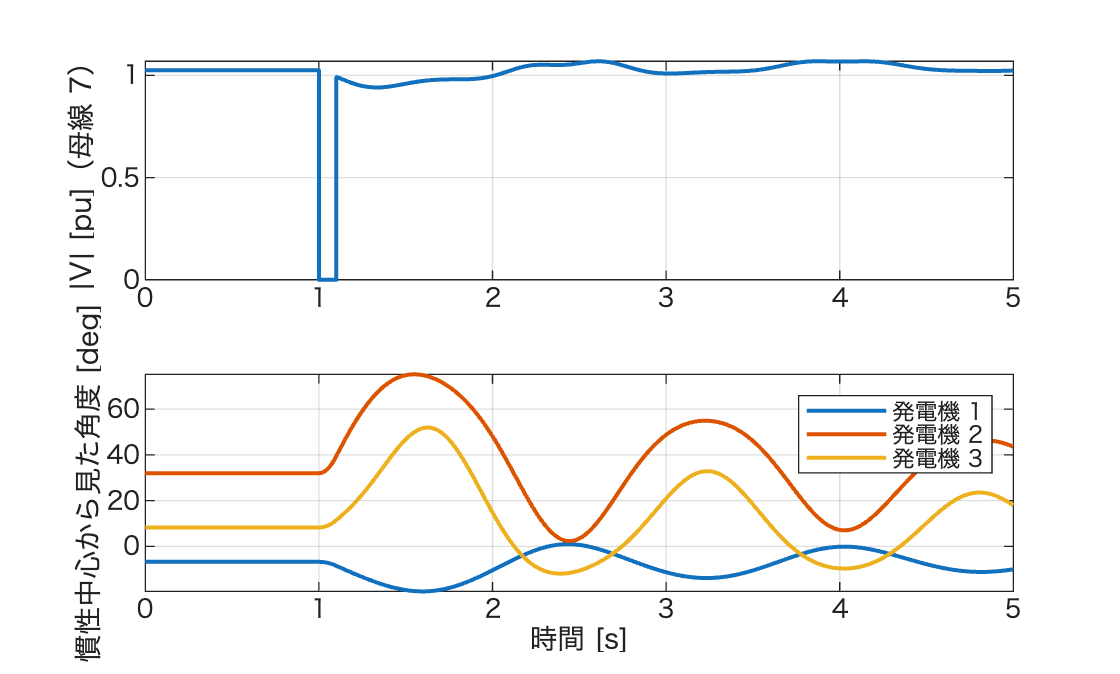

figure
tiledlayout(2, 1);
nexttile
plot(tab_Vabs.t, tab_Vabs.B007, LineWidth=1.5); grid on
ylabel("|V| [pu]（母線 7）")
nexttile
plot(tab_delta.t, rad2deg(tab_delta{:, ["B001SG1", "B002SG1", "B003SG1"]}), LineWidth=1.5); grid on
ylabel("慣性中心から見た角度 [deg]"); xlabel("時間 [s]")
legend(["発電機 1", "発電機 2", "発電機 3"], Location="northeast");

`get_trajectory` の [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultODE&method=get_trajectory')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。

**確かめる（省略できます）**

取り出した表の先頭を表示します。

head(tab_Vabs)

     t      B005       B007 
    ___    _______    ______

      0    0.99563    1.0258
    0.1    0.99563    1.0258
    0.2    0.99563    1.0258
    0.3    0.99563    1.0258
    0.4    0.99563    1.0258
    0.5    0.99563    1.0258
    0.6    0.99563    1.0258
    0.7    0.99563    1.0258



`odeResults` は、同じデータを母線と機器ごとに table に分けたものです。`t` が時刻、`Bus(i)` が `net.a_Bus{i}`、`Bus(i).Component(j)` がその母線の `a_Component{j}` に対応します。母線の電圧 `V` は実部 `Vreal` と虚部 `Vimag`、電流 `I` は `Ireal` と `Iimag`、電力 `PQ` は `P` と `Q` の table です。

r = result.odeResults

r = フィールドをもつ struct:
      t: [304×1 double]
    Bus: [1×9 struct]


r.Bus(7)

ans = フィールドをもつ struct:
    Component: [1×1 struct]
            V: [304×2 table]
            I: [304×2 table]
           PQ: [304×2 table]


head(r.Bus(7).V)

    Vreal      Vimag  
    ______    ________

    1.0236    0.066547
    1.0236    0.066547
    1.0236    0.066547
    1.0236    0.066547
    1.0236    0.066547
    1.0236    0.066547
    1.0236    0.066547
    1.0236    0.066547



機器の `X` が状態、`U` が入力、`Y` が出力、`I` が機器の電流で、列の名前は機器の `sv_x`、`sv_u`、`sv_y` です。

c = r.Bus(2).Component(1)

c = フィールドをもつ struct:
    X: [304×3 table]
    U: [304×2 table]
    Y: [304×2 table]
    I: [304×2 table]


head(c.X)

    delta        omega         Eq   
    ______    ___________    _______

    1.3131              0    0.76072
    1.3131    -1.8967e-17    0.76072
    1.3131    -3.2246e-17    0.76072
    1.3131    -4.0771e-17    0.76072
    1.3131    -4.2734e-17    0.76072
    1.3131    -3.9971e-17    0.76072
    1.3131    -3.4433e-17    0.76072
    1.3131    -2.9869e-17    0.76072



**注意:** 負荷（定インピーダンス負荷）には状態がないので、`X` は列のない table です。母線の順と機器のタグは `result.sv_bus` と `result.c_component` でも確かめられます。

## 6. 制御器の出力

制御器（AVR、PSS など）の状態と出力は `odeResults` には入っていません。`rm_variable` と `rm_output` の、`tab_variable` と `tab_output` の `Owner` が制御器のタグの列にあります。AVR の出力 `Vfield` は発電機の入力 `Vfield` を動かすので、発電機の入力として `get_trajectory` で取り出して描きます。

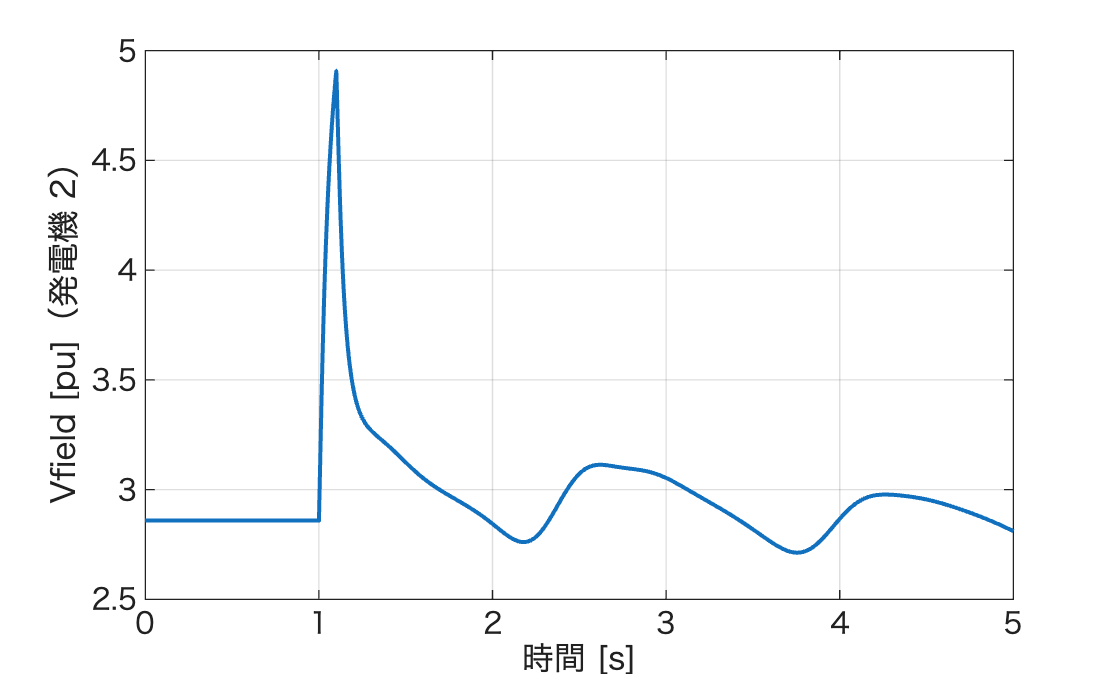

tab_Vfield = result.get_trajectory("Vfield", Owner="B002SG1");
figure
plot(tab_Vfield.t, tab_Vfield.B002SG1, LineWidth=1.5); grid on
xlabel("時間 [s]"); ylabel("Vfield [pu]（発電機 2）")

地絡で電圧が下がると、AVR は界磁電圧 `Vfield` を上げます。

**確かめる（省略できます）**

発電機 2 の AVR（`B002SG1CA1`）の変数を見ます。

result.tab_variable(result.tab_variable.Owner == "B002SG1CA1", ["Kind", "Name", "Equilibrium"])

ans = 6×3 table
    Kind      Name      Equilibrium
    ____    ________    ___________

    "x"     "Vtr"          1.025   
    "x"     "Vap"          2.859   
    "x"     "Vst"              0   
    "uc"    "Vref"        2.4545   
    "uc"    "Vpss"             0   
    "uc"    "Ifield"       2.859   


**注意:** 発電機の入力 `Vfield` は、制御器の出力と平衡点の値と `add_input` の値を合わせた、発電機に実際に加わる値です。この例では `add_input` がないので、AVR の出力と同じです。

## 7. ある時刻の値を取り出す（get_point）

`get_point(t)` は、時刻 `t` のすべての変数の値を、`tab_variable` の順の列ベクトルで返します。ソルバーの時刻の間は補間します。2 番目の引数に `tab_variable` の一部を渡すと、その行だけを返します。ここでは母線 7 の電圧の実部 `Vre` と虚部 `Vim` の 2 行を選びます。

地絡を除去した 1.1 秒はフェーズの境目なので、`Side` で除去の前（`"before"`）と後（`"after"`、既定）を選びます。

tab_V7 = result.tab_variable(result.tab_variable.Bus == "B007" & ismember(result.tab_variable.Kind, ["Vre", "Vim"]), :);
rv_before = result.get_point(1.1, tab_V7, Side="before");
rv_after  = result.get_point(1.1, tab_V7);

**確かめる（省略できます）**

左の列が除去の前、右の列が除去の後です。除去の前は地絡で電圧が 0、除去の後は電圧が戻っています。

[rv_before, rv_after]

ans =          0    0.9708
         0    0.2026


**注意:** `get_point` の値は、その時刻の点のまわりで近似線形化するときにも使えます（Step 8）。

## 8. 図を描く（plot_trajectory）

`plot_trajectory` は、時間応答の図を描きます。`Quantity` に描く量（`"Vabs"`（既定）・`"Vangle"`・`"P"`・`"Q"` と、状態や入力の名前）、`Bus` に母線のタグを指定します。`Parent` に figure や axes を渡すと、その中に描きます。4 つの量を 1 枚に並べます。

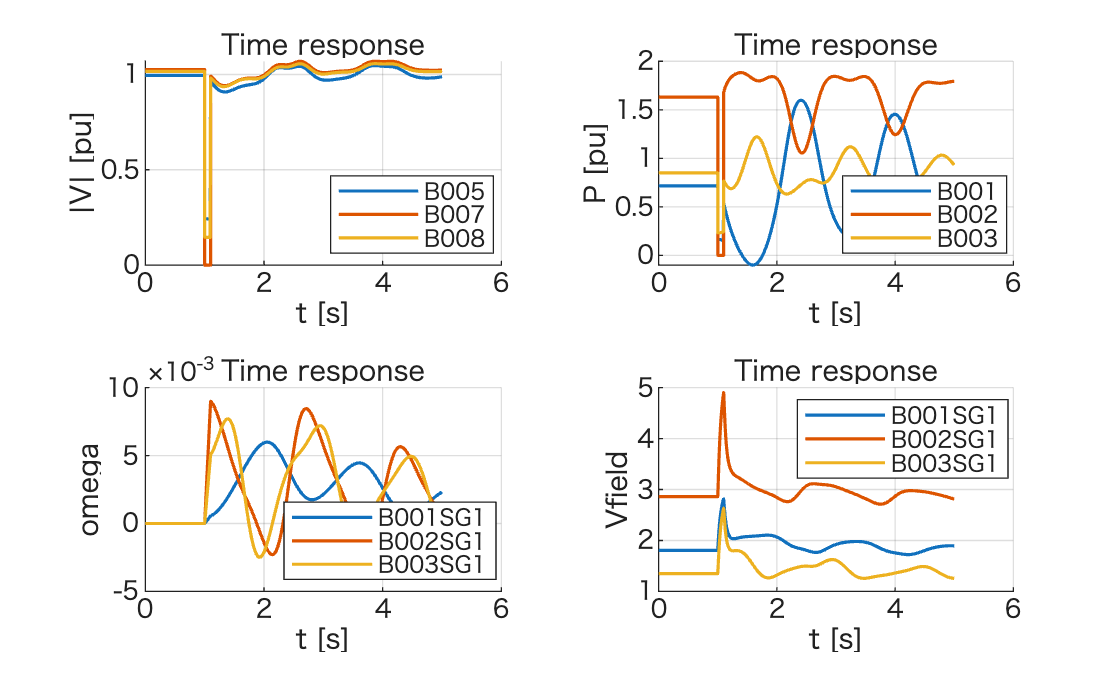

fig = figure;
layout = tiledlayout(fig, 2, 2);
result.plot_trajectory(Quantity="Vabs", Bus=["B005", "B007", "B008"], Parent=nexttile(layout));
result.plot_trajectory(Quantity="P", Bus=["B001", "B002", "B003"], Parent=nexttile(layout));
result.plot_trajectory(Quantity="omega", Parent=nexttile(layout));
G = result.plot_trajectory(Quantity="Vfield", Parent=nexttile(layout));

`plot_trajectory` は、描いた図のオブジェクトを返します。線の色や太さの変え方は Step 7 で説明します。`plot_trajectory` の [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultODE&method=plot_trajectory')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。

**確かめる（省略できます）**

class(G)

ans = 'GraphChart'

**注意:** 系統図の上の動き（`plot_diagram`）や、ばね質点の絵（`plot_spring_model`）は Step 7 と Part 4 で扱います。

## 9. 脱調を判定する（judge_out_of_step）

`judge_out_of_step` は、発電機の回転子の角度を基準と比べ、差が `Threshold`（既定 360°）を超えたら脱調と判定します。`Reference` は `"slack"`（slack 母線の発電機、既定）、`"COI"`（慣性中心）、発電機のタグのどれかです。

verdict = result.judge_out_of_step();
verdictCOI = result.judge_out_of_step(Reference="COI", Threshold=180);
verdictStop = resStop.judge_out_of_step();

3 つ目は、3.3 で脱調して途中で止めた結果の判定です。

**確かめる（省略できます）**

`Verdict` が判定（`"stable"`、`"out-of-step"`、`"incomplete"`）、`Time` が超えた時刻、`Units` が脱調した発電機、`MaxAngle` が角度の差の最大、`Reference` が基準です。

verdict

verdict = フィールドをもつ struct:
      Verdict: "stable"
         Time: NaN
        Units: [0×1 string]
     MaxAngle: 94.7816
    Reference: "B001SG1"
    Threshold: 360


verdictCOI

verdictCOI = フィールドをもつ struct:
      Verdict: "stable"
         Time: NaN
        Units: [0×1 string]
     MaxAngle: 75.2187
    Reference: "COI"
    Threshold: 180


verdictStop

verdictStop = フィールドをもつ struct:
      Verdict: "out-of-step"
         Time: 1.7144
        Units: "B002SG1"
     MaxAngle: 360
    Reference: "B001SG1"
    Threshold: 360


**注意:** 終わりの時刻まで計算できず、脱調も見つからなかったときは `"incomplete"` になります。

## 10. 構造体で受け取る（Format="struct"）

`Format="struct"` とすると、`ResultODE` の代わりに、系統の階層（母線 → 機器 → 制御器）に合わせた構造体を返します。

sol = net.simulate("fault", Format="struct", Progress="none");

**確かめる（省略できます）**

sol

sol = フィールドをもつ struct:
                     t: [304×1 double]
                 s_tag: "fault"
                 phase: [3×5 table]
          tab_variable: [72×8 table]
                 a_Bus: {9×1 cell}
    a_GlobalController: {0×1 cell}


sol.a_Bus{2}

ans = フィールドをもつ struct:
          s_tag: "B002"
              V: [304×2 table]
              I: [304×2 table]
              P: [304×1 table]
              Q: [304×1 table]
    a_Component: {[1×1 struct]}


**注意:** 構造体には `plot_trajectory` などのメソッドはありません。ふつうは既定の `ResultODE` を使います。

## 11. ファイルに書き出す（export）

`export` は結果をファイルに書き出します。形式は拡張子で決まり、`.csv` と `.xlsx` は 1 つの表（1 行が 1 つの時刻）、`.mat` は結果のデータです。CSV の列は時刻 `t`、母線ごとの電圧・電流・電力、機器ごとの状態と入力の順に並びます。

s_csv = fullfile(tempdir, "GUILDA_Step6_fault.csv");
result.export(s_csv);
s_mat = fullfile(tempdir, "GUILDA_Step6_fault.mat");
result.export(s_mat);

**確かめる（省略できます）**

書き出したファイルを読み込んで、大きさと列の名前、MAT ファイルの中身を表示します。

tab_csv = readtable(s_csv);
size(tab_csv)

ans =    304   121


tab_csv.Properties.VariableNames(1:12)

ans = 1×12 の cell 配列
    {'t'}    {'B001_Vreal'}    {'B001_Vimag'}    {'B001_Ireal'}    {'B001_Iimag'}    {'B001_P'}    {'B001_Q'}    {'B001SG1_delta'}    {'B001SG1_omega'}    {'B001SG1_Eq'}    {'B001SG1_Pmech'}    {'B001SG1_Vfield'}


whos("-file", s_mat)

  Name                Size             Bytes  Class     Attributes

  flag                1x1                  8  double              
  odeResults          1x1             292970  struct              
  options             1x1               2262  struct              
  output              1x1               3224  struct              
  rm_output         304x15             36480  double              
  rm_variable       304x72            175104  double              
  tab_output         15x8               8359  table               
  tab_variable       72x8              27403  table               



**注意:** ファイル名を省くと、日時の付いた名前で今のフォルダに書き出します。ほかのデータの入出力は Step 12 で説明します。

## まとめ

- `net.simulate` は、結果（`ResultODE`）、`flag`、`output` を返します。オプションで、ソルバー、許容誤差、出力の時刻、脱調での停止、計算時間の上限などを変えられます。

- 結果のデータは `rv_t`・`tab_variable`・`rm_variable`（すべての変数）、`odeResults`（母線と機器ごと）、`tab_output`・`rm_output`（出力）にあります。1 つの量の時間応答は `get_trajectory`、ある時刻の値は `get_point` で取り出せます。

- `plot_trajectory` で図を描き、`judge_out_of_step` で脱調を判定し、`export` でファイルに書き出しました。

## 次の Step と関係する Part

- 次の Step 7（可視化）では、`plot_*` が返す図のオブジェクトの使い方と、系統図・ばね質点モデルでの表示を説明します。

- 地絡の除去時間を変えて臨界除去時間を求める例や、ガバナの効果の比べ方は Part 3（時間シミュレーション）で扱います（`Part3_TimeSimulation.mlx`）。

[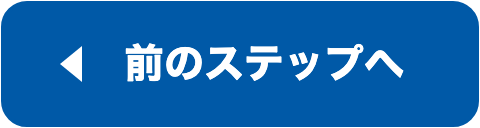](matlab:open('Step5_SimulationScenario.mlx'))　　[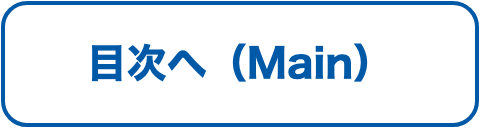](matlab:open('Main.mlx'))　　[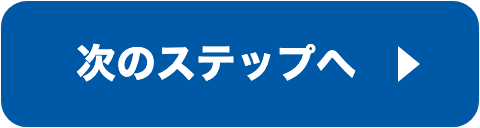](matlab:open('Step7_Visualization.mlx'))